## Load Data & Palm fitting

clc
clear all

tic 

addpath('angle data\');
addpath('Data\');
addpath("Fitted vertices\");
addpath('D:\GitHub\Hand_deformation_model\data_SW\');
addpath(genpath('../external'));
addpath('D:\GitHub\Hand_deformation_model\functions');
addpath('D:\GitHub\Hand_deformation_model\external\registration\');
addpath('D:\GitHub\Hand_deformation_model\200916_registration_hand_SW\');

load('HY_mesh_t2.mat');
%load('hy_mesh_n5.mat'); %template

[points.vertices, points.faces, points.FB, points.H] = function_loading_ply_file('HY_pos7.ply'); % target scan
points.normals = per_vertex_normals(points.vertices, points.faces);

%% search template LM index
LMt = function_get_LM_from_iges('template_LMs.igs'); % template landmark by hand
LMs = function_get_LM_from_iges('HY_pos2.igs'); % scan landmark by hand 
LMt_Idx = zeros(size(LMt,1),1);
m = size(mesh.vertices, 1);
for i = 1:size(LMt,1)
delta = mesh.vertices - repmat(LMt(i, :), m, 1);
distances = sum(delta .^ 2, 2);
[~, j] = min(distances);
LMt_Idx(i,:) = j; % template landmark index detection
end
for i = 1:size(LMt,1)
LMt(i,:) = mesh.vertices(LMt_Idx(i),:); % template landmark update
end
clear m delta distances i j 


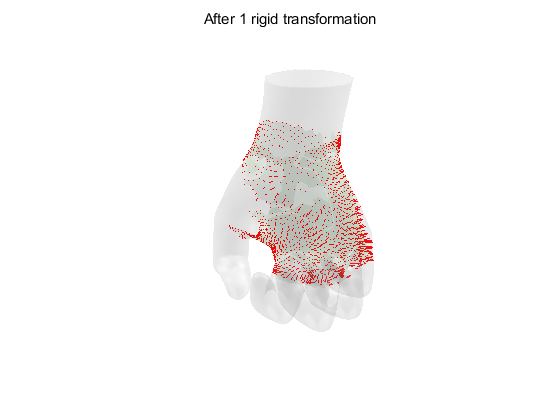

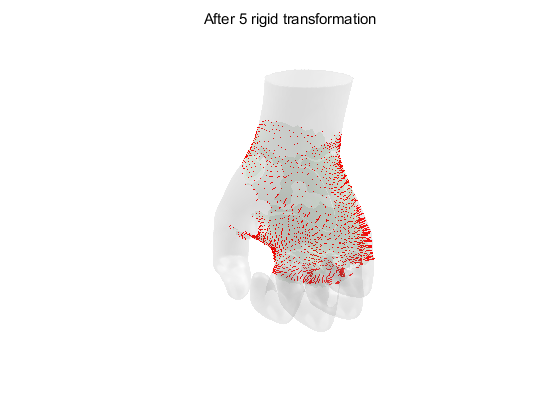

% palm scale 
% Landmarks for palm alignment & hand scale
LMs_PLM = function_get_LM_from_iges('HY_pos7_PLM.igs'); % LM for scan
%LMt_PLM = function_get_LM_from_iges('LMt.igs'); % LM for template
LMt_PLM = function_get_LM_from_iges('HY_pos2_PLM.igs'); % LM for template
LMs_PLM = LMs_PLM'; LMt_PLM = LMt_PLM';
[regParams,~,~] = absor(LMt_PLM,LMs_PLM);

% update vertices & CoR
mesh.vertices = apply_matrix(regParams.M, mesh.vertices, 1);
for i = 1:22
    mesh.spheres{1,i}.center = apply_matrix(regParams.M, mesh.spheres{1,i}.center, 1);
    mesh.centers(i,:) = mesh.spheres{1,i}.center;
end

% palm registration
keep = ismember(mesh.assignment, 1:5);
[vertices, faces] = filter_vertices(mesh.vertices, mesh.faces, keep);
normals = per_vertex_normals(mesh.vertices, mesh.faces);
normals = normals(keep, :);
pairs = compute_correspondences_palm(vertices, normals, points.vertices, points.normals);
view_angle = [207,10];
figure()
view(view_angle);
transform = eye(4);
for i = 1 : 5
    delta = compute_transformation(vertices, points.vertices, points.normals, pairs);
    transform = delta * transform;
    vertices = apply_matrix(delta, vertices);
    normals = apply_matrix(delta, normals, 0);
    pairs = compute_correspondences_palm(vertices, normals, points.vertices, points.normals);
    v = get(gca, 'view'); 
    trimesh(faces, vertices(:, 1), vertices(:, 2), vertices(:, 3), 'EdgeColor', 'none', 'FaceColor', [0.4, 0.9, 0.4], 'FaceAlpha', 0.1);
    hold on;
    trimesh(points.faces, points.vertices(:, 1), points.vertices(:, 2), points.vertices(:, 3), 'EdgeColor', 'none', 'FaceColor', [0.8, 0.8, 0.8], 'FaceAlpha', 0.1);
    plot3( ...
        [vertices(pairs(:, 1), 1), points.vertices(pairs(:, 2), 1)]', ...
        [vertices(pairs(:, 1), 2), points.vertices(pairs(:, 2), 2)]', ...
        [vertices(pairs(:, 1), 3), points.vertices(pairs(:, 2), 3)]', ...
    'Color', 'red');
    hold off;
    view([-90,0]);
    camlight;
    view([90,0]);
    camlight;
    axis equal;
    grid off;
    lighting gouraud;
    axis off;
    title(['After ', num2str(i), ' rigid transformation']);
    set(gca, 'view', v);
    pause(0.01);
end


transforms{2} = transform;

% update vertices & CoR
mesh.vertices = apply_matrix(transform, mesh.vertices, 1); % update current vertices
mesh.normals = per_vertex_normals(mesh.vertices, faces);
for i = 1:22
    mesh.spheres{1,i}.center = apply_matrix(transform, mesh.spheres{1,i}.center,1);
    mesh.centers(i,:) = mesh.spheres{1,i}.center;
end

clear Bfit ErrorStats regParams delta faces h i keep LMs_PLM LMt_PLM pairs transform transforms


% figure()
% hold on;
% axis equal
% axis off
% h = trimesh(mesh.faces, mesh.vertices(:, 1), mesh.vertices(:, 2), mesh.vertices(:, 3), 'EdgeColor', 'none', 'FaceColor', [0.5, 0.5, 0.5], 'FaceAlpha', 1);
% lighting gouraud;
% view([193, -4]);
% camlight;
% view([185, 8]);
% camlight;
% hold off;

%save hy_mesh_n5_palm_fitted.mat mesh %template

%mesh.spheres{1,22}.center

## **Data visualization**

% figure()
% hold on
% axis equal
% axis off
% 
% %scatter3(mesh.vertices(:,1),mesh.vertices(:,2),mesh.vertices(:,3),'.', 'MarkerEdgeColor',[190/255, 240/255, 251/255]);
% trimesh(mesh.faces, mesh.vertices(:, 1), mesh.vertices(:, 2), mesh.vertices(:, 3), 'EdgeColor', 'none', 'FaceColor', [0.5, 0.5, 0.5], 'FaceAlpha', 1);
% %trimesh(points.faces, points.vertices(:, 1), points.vertices(:, 2), points.vertices(:, 3), 'EdgeColor', 'none', 'FaceColor', [0.8, 0.8, 0.8], 'FaceAlpha', 0.5);
% %plot3(centers(:,1),centers(:,2),centers(:,3))
% view([-90,0]);
% camlight;
% view([90, 0]);
% camlight;
% axis equal;
% grid off;
% lighting gouraud;
% axis off;
% view([185, 8]);
% camlight;
% 
% hold off

## Angle load and application

load('Ags.mat');
angle = Ags(:,5);
tr_mesh = transform_angle(mesh, angle);
mesh = tr_mesh;


% % mesh spheres center --> centers 
% for i = 1:22
% centers(i,:) = mesh.spheres{1,i}.center;
% end 
% 
% % centers info --> mesh spheres center
% for i = 1:22
% mesh.spheres{1,i}.center = centers(i,:);
% end 


## Thumb registration

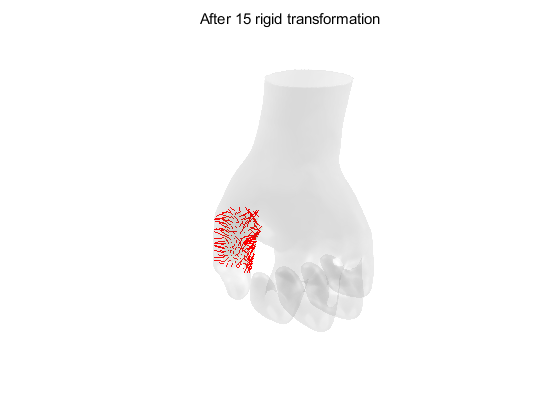

%% Things to do (thumb registration - temporal) 

load('assignment_new.mat');

%tic

FRP_dorsal_segment = [6 107 108];
FRP_cor = [20 19 18];
FRP_digits{1} = [6:8];
FRP_cor_tr{1} = [17:19];
transform_order= [3 4 5];

axes = compute_bone_axes(mesh.spheres);
normals = per_vertex_normals(mesh.vertices, mesh.faces);

h3 = [];
h4 = [];

transforms = cell(1, 18);
for i = 1 : 18
    transforms{i} = eye(4);
end

for j = 2 %1:3
vertices = mesh.vertices;
faces = mesh.faces;
normals = per_vertex_normals(vertices, faces);
keep = ismember(assignment_new, FRP_dorsal_segment(j));
[vertices, faces] = filter_vertices(vertices, faces, keep);
normals = normals(keep, :);
pairs = compute_correspondences_new(vertices, normals, points.vertices, points.normals, 20, cos(45*pi/180));

transform = eye(4);

figure()
    view(view_angle);
    for i = 1 : 15
        delete(h3);
        delete(h4);
        delta = compute_transformation(vertices, points.vertices, points.normals, pairs);
        delta = constraint_transformation(delta, mesh.spheres{1,FRP_cor(j)}.center); %centers_c(FRP_cor(j),:));
        transform = delta * transform;
        vertices = apply_matrix(delta, vertices);
        normals = apply_matrix(delta, normals, 0);
        
       pairs = compute_correspondences_new(vertices, normals, points.vertices, points.normals, 25, cos(45*pi/180));

        v = get(gca, 'view');
        trimesh(faces, vertices(:, 1), vertices(:, 2), vertices(:, 3), 'EdgeColor', 'none', 'FaceColor', [0.4, 0.9, 0.4], 'FaceAlpha', 0.1);
        hold on;
        h3 = trimesh(points.faces, points.vertices(:, 1), points.vertices(:, 2), points.vertices(:, 3), 'EdgeColor', 'none', 'FaceColor', [0.8, 0.8, 0.8], 'FaceAlpha', 0.1);
        h4 = plot3( ...
            [vertices(pairs(:, 1), 1), points.vertices(pairs(:, 2), 1)]', ...
            [vertices(pairs(:, 1), 2), points.vertices(pairs(:, 2), 2)]', ...
            [vertices(pairs(:, 1), 3), points.vertices(pairs(:, 2), 3)]', ...
        'Color', 'red');
        hold off;
        view([-90, 0]);
        camlight;
        view([90, 0]);
        camlight;
        axis equal;
        grid off;
        lighting gouraud;
        axis off;
        title(['After ', num2str(i), ' rigid transformation']);
        set(gca, 'view', v);
        pause(0.01);
    end

transforms{transform_order(j)} = transform;

% D1 CMC
transforms{3} = transforms{3};
% D1 MCP
transforms{4} = transforms{4} * transforms{3};
% D1 IP
transforms{5} = transforms{5} * transforms{4};
% D2 MCP
transforms{6} = transforms{6};
% D2 PIP
transforms{7} = transforms{7} * transforms{6};
% D2 DIP
transforms{8} = transforms{8} * transforms{7};
% D3 MCP
transforms{9} = transforms{9};
% D3 PIP
transforms{10} = transforms{10} * transforms{9};
% D3 DIP
transforms{11} = transforms{11} * transforms{10};
% D4 MCP
transforms{12} = transforms{12};
% D4 PIP
transforms{13} = transforms{13} * transforms{12};
% D4 DIP
transforms{14} = transforms{14}  * transforms{13};
% D5 MCP
transforms{16} = transforms{16};
% D5 PIP
transforms{17} = transforms{17} * transforms{16};
% D5 DIP
transforms{18} = transforms{18} * transforms{17};

transformed = skin_dualquat(mesh, transforms);
    for i = 1:18
         transformed.centers(i,:) = transformed.spheres{1,i}.center;
    end
mesh = transformed;

h3 = [];
h4 = [];

    transforms = cell(1, 18);
    for i = 1 : 18
        transforms{i} = eye(4);
    end

end 


%toc


## Digits Register

### 1. D2 Register

load('assignment_new.mat');

%tic 
% D2 MCP fit
angle = zeros(19,1);
FRP_dorsal_segment = 109;
record = [];
for ag2 = -0.4:0.0167:0.4 % size = 48
    angle = zeros(19,1);
    angle(4) = ag2;
    tr_mesh = transform_angle(mesh, angle);
    mean_distance = mean_dist_tester(tr_mesh, points, FRP_dorsal_segment, assignment_new);
    record = [record; ag2 mean_distance];
end

mean distance = 7.73
mean distance = 7.02
mean distance = 6.88
mean distance = 6.24
mean distance = 5.95
mean distance = 6.45
mean distance = 5.89
mean distance = 5.41
mean distance = 4.19
mean distance = 4.48
mean distance = 4.17
mean distance = 4.41
mean distance = 4.27
mean distance = 4.68
mean distance = 4.72
mean distance = 3.85
mean distance = 3.56
mean distance = 3.62
mean distance = 4.32
mean distance = 4.98
mean distance = 4.71
mean distance = 4.55
mean distance = 4.27
mean distance = 4.56
mean distance = 5.43
mean distance = 5.96
mean distance = 5.85
mean distance = 6.53
mean distance = 6.11
mean distance = 6.92
mean distance = 6.74
mean distance = 7.36
mean distance = 8.21
mean distance = 8.31
mean distance = 8.41
mean distance = 8.83
mean distance = 9.01
mean distance = 9.25
mean distance = 10.06
mean distance = 9.82
mean distance = 10.41
mean distance = 10.82
mean distance = 10.66
mean distance = 11.02
mean distance = 11.03
mean distance = 11.22
mean distance = 11.09
mean 

[~,col] = min(record(:,2));
angle = zeros(19,1);
angle(4) = record(col,1);
mesh = transform_angle(mesh, angle); % adjust MCP posture & update mesh

% D2 PIP fit
FRP_dorsal_segment = 110;
record = [];
for ag3 = -0.4:0.0167:0.4 % size = 67
        angle = zeros(19,1);
        angle(5) = ag3;
        tr_mesh = transform_angle(mesh, angle);
        mean_distance = mean_dist_tester(tr_mesh, points, FRP_dorsal_segment, assignment_new);
        record = [record; ag3 mean_distance];
end

mean distance = 6.90
mean distance = 6.76
mean distance = 6.13
mean distance = 5.77
mean distance = 6.19
mean distance = 5.72
mean distance = 5.72
mean distance = 5.15
mean distance = 4.95
mean distance = 5.85
mean distance = 4.69
mean distance = 5.44
mean distance = 4.77
mean distance = 4.88
mean distance = 5.37
mean distance = 3.85
mean distance = 5.05
mean distance = 5.05
mean distance = 4.46
mean distance = 5.08
mean distance = 3.23
mean distance = 3.81
mean distance = 3.65
mean distance = 3.82
mean distance = 3.49
mean distance = 4.11
mean distance = 3.97
mean distance = 4.37
mean distance = 3.89
mean distance = 4.11
mean distance = 3.72
mean distance = 4.39
mean distance = 4.38
mean distance = 3.82
mean distance = 5.14
mean distance = 4.42
mean distance = 4.50
mean distance = 4.41
mean distance = 5.29
mean distance = 4.92
mean distance = 4.86
mean distance = 5.12
mean distance = 5.03
mean distance = 6.11
mean distance = 5.99
mean distance = 5.71
mean distance = 6.30
mean distance

[~,col] = min(record(:,2));
angle = zeros(19,1);
angle(5) = record(col,1);
Angle_opt.D2_PIP.FxEt = record(col,1);
mesh = transform_angle(mesh, angle); % adjust MCP posture & update mesh

% D2 MCP supination/pronation fit
FRP_dorsal_segment = 110;
record = [];
for ag3 = -0.28:0.035:0.28 % size = 9
        angle_supr = zeros(4,1);
        angle_supr(1) = ag3;
        tr_mesh = transform_sup_pro_angle(mesh, angle_supr);
        mean_distance = mean_dist_tester(tr_mesh, points, FRP_dorsal_segment, assignment_new);
        record = [record; ag3 mean_distance];
end

mean distance = 6.63
mean distance = 5.91
mean distance = 5.46
mean distance = 5.25
mean distance = 5.13
mean distance = 4.43
mean distance = 4.97
mean distance = 4.08
mean distance = 3.60
mean distance = 4.20
mean distance = 4.58
mean distance = 3.85
mean distance = 5.27
mean distance = 4.37
mean distance = 5.12
mean distance = 5.03
mean distance = 5.15


[~,col] = min(record(:,2));
angle_supr = zeros(4,1);
angle_supr(1) = record(col,1);
Angle_opt.D2_PIP.SpPr = record(col,1);
mesh = transform_sup_pro_angle(mesh, angle_supr); % adjust MCP posture & update mesh

% D2 DIP
FRP_dorsal_segment = 111;
record = [];
for ag3 = -0.15:0.03:0.75 % size = 26
        angle = zeros(19,1);
        angle(6) = ag3;
        tr_mesh = transform_angle(mesh, angle);
        mean_distance = mean_dist_tester(tr_mesh, points, FRP_dorsal_segment, assignment_new);
        record = [record; ag3 mean_distance];
end

mean distance = 8.29
mean distance = 8.96
mean distance = 8.24
mean distance = 7.80
mean distance = 7.43
mean distance = 6.74
mean distance = 7.40
mean distance = 7.17
mean distance = 6.73
mean distance = 6.15
mean distance = 5.60
mean distance = 6.18
mean distance = 5.57
mean distance = 4.68
mean distance = 5.16
mean distance = 4.91
mean distance = 5.17
mean distance = 4.97
mean distance = 4.27
mean distance = 3.83
mean distance = 4.69
mean distance = 4.55
mean distance = 4.63
mean distance = 4.20
mean distance = 4.91
mean distance = 4.60
mean distance = 4.57
mean distance = 4.79
mean distance = 5.46
mean distance = 5.31
mean distance = 5.67


[~,col] = min(record(:,2));
angle = zeros(19,1);
angle(6) = record(col,1);
Angle_opt.D2_DIP.FxEt = record(col,1);
mesh = transform_angle(mesh, angle); % adjust MCP posture & update mesh



### 2. D3 Register

% D3 MCP fit
FRP_dorsal_segment = 112;
record = [];
for ag2 = -0.4:0.0167:0.4 % size = 48
    angle = zeros(19,1);
    angle(7) = ag2;
    tr_mesh = transform_angle(mesh, angle);
    mean_distance = mean_dist_tester(tr_mesh, points, FRP_dorsal_segment, assignment_new);
    record = [record; ag2 mean_distance];
end

mean distance = 8.36
mean distance = 8.74
mean distance = 8.19
mean distance = 7.97
mean distance = 7.66
mean distance = 7.54
mean distance = 7.10
mean distance = 6.88
mean distance = 6.27
mean distance = 6.86
mean distance = 5.38
mean distance = 6.79
mean distance = 6.14
mean distance = 5.35
mean distance = 5.60
mean distance = 5.90
mean distance = 5.91
mean distance = 6.46
mean distance = 5.99
mean distance = 5.52
mean distance = 6.74
mean distance = 6.36
mean distance = 6.59
mean distance = 6.80
mean distance = 8.02
mean distance = 7.64
mean distance = 7.75
mean distance = 8.69
mean distance = 8.64
mean distance = 9.21
mean distance = 9.86
mean distance = 10.07
mean distance = 10.26
mean distance = 10.95
mean distance = 10.74
mean distance = 10.88
mean distance = 11.20
mean distance = 11.76
mean distance = 11.96
mean distance = 11.62
mean distance = 11.77
mean distance = 11.60
mean distance = 11.75
mean distance = 11.78
mean distance = 11.92
mean distance = 11.02
mean distance = 11.

[~,col] = min(record(:,2));
angle = zeros(19,1);
angle(7) = record(col,1);
mesh = transform_angle(mesh, angle); % adjust MCP posture & update mesh

FRP_dorsal_segment = 113;
record = [];
for ag3 = -0.4:0.0167:0.4 % size = 67
        angle = zeros(19,1);
        angle(8) = ag3;
        tr_mesh = transform_angle(mesh, angle);
        mean_distance = mean_dist_tester(tr_mesh, points, FRP_dorsal_segment, assignment_new);
        record = [record; ag3 mean_distance];
end

mean distance = 8.24
mean distance = 8.60
mean distance = 8.28
mean distance = 8.29
mean distance = 8.55
mean distance = 8.81
mean distance = 8.01
mean distance = 8.23
mean distance = 9.01
mean distance = 8.59
mean distance = 8.24
mean distance = 8.34
mean distance = 7.25
mean distance = 7.93
mean distance = 7.63
mean distance = 7.71
mean distance = 7.28
mean distance = 7.49
mean distance = 7.47
mean distance = 7.13
mean distance = 7.08
mean distance = 7.06
mean distance = 8.28
mean distance = 7.50
mean distance = 6.91
mean distance = 6.81
mean distance = 6.90
mean distance = 7.68
mean distance = 6.61
mean distance = 6.50
mean distance = 7.14
mean distance = 6.37
mean distance = 5.89
mean distance = 6.01
mean distance = 6.22
mean distance = 5.98
mean distance = 5.26
mean distance = 5.93
mean distance = 6.29
mean distance = 5.82
mean distance = 5.82
mean distance = 5.40
mean distance = 6.23
mean distance = 5.65
mean distance = 5.85
mean distance = 5.76
mean distance = 6.31
mean distance

[~,col] = min(record(:,2));
angle = zeros(19,1);
angle(8) = record(col,1);
mesh = transform_angle(mesh, angle); % adjust MCP posture & update mesh

FRP_dorsal_segment = 113;
record = [];
for ag3 = -0.28:0.035:0.28 % size = 9
        angle_supr = zeros(4,1);
        angle_supr(2) = ag3;
        tr_mesh = transform_sup_pro_angle(mesh, angle_supr);
        mean_distance = mean_dist_tester(tr_mesh, points, FRP_dorsal_segment, assignment_new);
        record = [record; ag3 mean_distance];
end

mean distance = 5.00
mean distance = 5.24
mean distance = 4.59
mean distance = 4.63
mean distance = 4.84
mean distance = 5.35
mean distance = 5.16
mean distance = 5.22
mean distance = 5.70
mean distance = 6.27
mean distance = 6.68
mean distance = 7.53
mean distance = 6.63
mean distance = 7.07
mean distance = 8.13
mean distance = 8.18
mean distance = 9.02


[~,col] = min(record(:,2));
angle_supr = zeros(4,1);
angle_supr(2) = record(col,1);
mesh = transform_sup_pro_angle(mesh, angle_supr); % adjust MCP posture & update mesh

FRP_dorsal_segment = 114;
record = [];
for ag3 = -0.15:0.03:0.75 % size = 26
        angle = zeros(19,1);
        angle(9) = ag3;
        tr_mesh = transform_angle(mesh, angle);
        mean_distance = mean_dist_tester(tr_mesh, points, FRP_dorsal_segment, assignment_new);
        record = [record; ag3 mean_distance];
end

mean distance = 8.36
mean distance = 8.78
mean distance = 8.97
mean distance = 8.81
mean distance = 7.12
mean distance = 6.88
mean distance = 7.06
mean distance = 7.79
mean distance = 5.23
mean distance = 7.01
mean distance = 6.52
mean distance = 5.50
mean distance = 5.11
mean distance = 5.60
mean distance = 5.35
mean distance = 4.73
mean distance = 5.32
mean distance = 5.46
mean distance = 5.29
mean distance = 5.88
mean distance = 5.03
mean distance = 6.39
mean distance = 6.47
mean distance = 5.76
mean distance = 6.67
mean distance = 6.59
mean distance = 6.74
mean distance = 6.82
mean distance = 6.35
mean distance = 7.21
mean distance = 7.49


[~,col] = min(record(:,2));
angle = zeros(19,1);
angle(9) = record(col,1);
mesh = transform_angle(mesh, angle); % adjust MCP posture & update mesh


### 3. D4 Register

% D4 MCP fit
FRP_dorsal_segment = 115;
record = [];
for ag2 = -0.4:0.0167:0.4 % size = 48
    angle = zeros(19,1);
    angle(10) = ag2;
    tr_mesh = transform_angle(mesh, angle);
    mean_distance = mean_dist_tester(tr_mesh, points, FRP_dorsal_segment, assignment_new);
    record = [record; ag2 mean_distance];
end

mean distance = 7.82
mean distance = 7.16
mean distance = 7.77
mean distance = 6.88
mean distance = 7.15
mean distance = 7.72
mean distance = 8.09
mean distance = 6.54
mean distance = 7.57
mean distance = 7.57
mean distance = 5.79
mean distance = 6.38
mean distance = 7.40
mean distance = 7.35
mean distance = 7.15
mean distance = 6.74
mean distance = 8.32
mean distance = 5.05
mean distance = 6.05
mean distance = 7.66
mean distance = 6.95
mean distance = 7.37
mean distance = 7.28
mean distance = 6.91
mean distance = 6.53
mean distance = 8.34
mean distance = 8.38
mean distance = 8.13
mean distance = 7.35
mean distance = 8.92
mean distance = 9.19
mean distance = 10.63
mean distance = 9.93
mean distance = 9.72
mean distance = 10.19
mean distance = 10.45
mean distance = 11.03
mean distance = 10.78
mean distance = 11.63
mean distance = 11.35
mean distance = 11.83
mean distance = 11.93
mean distance = 11.78
mean distance = 12.11
mean distance = 11.47
mean distance = 11.73
mean distance = 11.92

[~,col] = min(record(:,2));
angle = zeros(19,1);
angle(10) = record(col,1);
mesh = transform_angle(mesh, angle); % adjust MCP posture & update mesh

FRP_dorsal_segment = 116;
record = [];
for ag3 = -0.4:0.0167:0.4 % size = 67
        angle = zeros(19,1);
        angle(11) = ag3;
        tr_mesh = transform_angle(mesh, angle);
        mean_distance = mean_dist_tester(tr_mesh, points, FRP_dorsal_segment, assignment_new);
        record = [record; ag3 mean_distance];
end

mean distance = 7.31
mean distance = 6.83
mean distance = 7.31
mean distance = 6.69
mean distance = 6.45
mean distance = 5.42
mean distance = 7.18
mean distance = 6.64
mean distance = 5.94
mean distance = 6.34
mean distance = 5.98
mean distance = 6.82
mean distance = 6.11
mean distance = 6.66
mean distance = 6.42
mean distance = 5.57
mean distance = 5.39
mean distance = 5.60
mean distance = 6.02
mean distance = 5.97
mean distance = 5.11
mean distance = 6.01
mean distance = 6.64
mean distance = 5.02
mean distance = 6.43
mean distance = 6.07
mean distance = 5.88
mean distance = 5.23
mean distance = 5.53
mean distance = 6.77
mean distance = 5.44
mean distance = 6.09
mean distance = 5.73
mean distance = 5.70
mean distance = 6.58
mean distance = 6.86
mean distance = 6.11
mean distance = 7.85
mean distance = 7.44
mean distance = 6.51
mean distance = 7.30
mean distance = 7.17
mean distance = 6.68
mean distance = 7.40
mean distance = 8.10
mean distance = 7.36
mean distance = 7.09
mean distance

[~,col] = min(record(:,2));
angle = zeros(19,1);
angle(11) = record(col,1);
Angle_opt.D4_PIP.FxEt = record(col,1);
mesh = transform_angle(mesh, angle); % adjust MCP posture & update mesh

FRP_dorsal_segment = 116;
record = [];
for ag3 = -0.28:0.07:0.28 % size = 9
        angle_supr = zeros(4,1);
        angle_supr(3) = ag3;
        tr_mesh = transform_sup_pro_angle(mesh, angle_supr);
        mean_distance = mean_dist_tester(tr_mesh, points, FRP_dorsal_segment, assignment_new);
        record = [record; ag3 mean_distance];
end

mean distance = 4.06
mean distance = 4.77
mean distance = 5.35
mean distance = 5.65
mean distance = 5.62
mean distance = 5.94
mean distance = 6.89
mean distance = 7.19
mean distance = 7.82


[~,col] = min(record(:,2));
angle_supr = zeros(4,1);
angle_supr(3) = record(col,1);
mesh = transform_sup_pro_angle(mesh, angle_supr); % adjust MCP posture & update mesh

% D4 DIP fit
FRP_dorsal_segment = 117;
record = [];
for ag3 = -0.5:0.03:1.3 % size = 26
        angle = zeros(19,1);
        angle(12) = ag3;
        tr_mesh = transform_angle(mesh, angle);
        mean_distance = mean_dist_tester(tr_mesh, points, FRP_dorsal_segment, assignment_new);
        record = [record; ag3 mean_distance];
end

mean distance = 9.58
mean distance = 10.05
mean distance = 9.33
mean distance = 9.00
mean distance = 9.64
mean distance = 9.59
mean distance = 9.42
mean distance = 9.71
mean distance = 9.51
mean distance = 8.61
mean distance = 9.53
mean distance = 9.61
mean distance = 9.17
mean distance = 9.60
mean distance = 9.88
mean distance = 9.59
mean distance = 9.33
mean distance = 9.68
mean distance = 9.56
mean distance = 9.46
mean distance = 9.53
mean distance = 9.14
mean distance = 8.46
mean distance = 9.09
mean distance = 8.33
mean distance = 8.87
mean distance = 8.89
mean distance = 8.75
mean distance = 8.44
mean distance = 7.54
mean distance = 8.54
mean distance = 8.74
mean distance = 8.15
mean distance = 8.57
mean distance = 8.13
mean distance = 9.03
mean distance = 9.21
mean distance = 9.00
mean distance = 8.94
mean distance = 8.93
mean distance = 8.64
mean distance = 9.11
mean distance = 9.25
mean distance = 9.31
mean distance = 9.46
mean distance = 9.73
mean distance = 9.95
mean distanc

[~,col] = min(record(:,2));
angle = zeros(19,1);
angle(12) = record(col,1);
Angle_opt.D4_DIP.FxEt = record(col,1);
mesh = transform_angle(mesh, angle); % adjust MCP posture & update mesh


### 4. D5 register

% D5 MCP fit
FRP_dorsal_segment = 118;
record = [];
for ag2 = -0.4:0.0167:0.4 % size = 48
    angle = zeros(19,1);
    angle(13) = ag2;
    tr_mesh = transform_angle(mesh, angle);
    mean_distance = mean_dist_tester(tr_mesh, points, FRP_dorsal_segment, assignment_new);
    record = [record; ag2 mean_distance];
end

mean distance = 10.16
mean distance = 9.95
mean distance = 10.54
mean distance = 9.95
mean distance = 9.24
mean distance = 9.12
mean distance = 9.16
mean distance = 9.53
mean distance = 8.69
mean distance = 8.39
mean distance = 7.79
mean distance = 7.57
mean distance = 8.04
mean distance = 6.47
mean distance = 6.78
mean distance = 7.21
mean distance = 6.63
mean distance = 6.30
mean distance = 7.48
mean distance = 6.82
mean distance = 6.13
mean distance = 5.80
mean distance = 7.53
mean distance = 5.93
mean distance = 6.16
mean distance = 6.95
mean distance = 5.33
mean distance = 6.80
mean distance = 6.39
mean distance = 6.89
mean distance = 5.20
mean distance = 5.47
mean distance = 6.34
mean distance = 5.80
mean distance = 6.63
mean distance = 6.00
mean distance = 6.07
mean distance = 7.32
mean distance = 7.21
mean distance = 7.82
mean distance = 7.52
mean distance = 8.01
mean distance = 7.38
mean distance = 7.69
mean distance = 8.39
mean distance = 8.35
mean distance = 7.98
mean distan

[~,col] = min(record(:,2));
angle = zeros(19,1);
angle(13) = record(col,1);
mesh = transform_angle(mesh, angle); % adjust MCP posture & update mesh

FRP_dorsal_segment = 119;
record = [];
for ag3 = -0.4:0.0167:0.4 % size = 67
        angle = zeros(19,1);
        angle(14) = ag3;
        tr_mesh = transform_angle(mesh, angle);
        mean_distance = mean_dist_tester(tr_mesh, points, FRP_dorsal_segment, assignment_new);
        record = [record; ag3 mean_distance];
end

mean distance = 9.31
mean distance = 8.72
mean distance = 8.28
mean distance = 9.33
mean distance = 8.77
mean distance = 8.89
mean distance = 10.49
mean distance = 9.45
mean distance = 9.26
mean distance = 9.23
mean distance = 9.54
mean distance = 8.55
mean distance = 8.57
mean distance = 8.75
mean distance = 9.68
mean distance = 7.89
mean distance = 8.53
mean distance = 8.12
mean distance = 7.81
mean distance = 8.97
mean distance = 7.71
mean distance = 8.14
mean distance = 9.00
mean distance = 8.93
mean distance = 7.92
mean distance = 7.83
mean distance = 8.48
mean distance = 7.76
mean distance = 8.80
mean distance = 7.92
mean distance = 8.31
mean distance = 6.74
mean distance = 7.33
mean distance = 7.17
mean distance = 7.15
mean distance = 7.28
mean distance = 7.51
mean distance = 7.56
mean distance = 7.43
mean distance = 6.58
mean distance = 5.61
mean distance = 5.38
mean distance = 5.60
mean distance = 6.00
mean distance = 5.71
mean distance = 5.78
mean distance = 5.59
mean distanc

[~,col] = min(record(:,2));
angle = zeros(19,1);
angle(14) = record(col,1);
Angle_opt.D5_PIP.FxEt = record(col,1);
mesh = transform_angle(mesh, angle); % adjust MCP posture & update mesh

FRP_dorsal_segment = 119;
record = [];
for ag3 = -0.28:0.07:0.28 % size = 9
        angle_supr = zeros(4,1);
        angle_supr(4) = ag3;
        tr_mesh = transform_sup_pro_angle(mesh, angle_supr);
        mean_distance = mean_dist_tester(tr_mesh, points, FRP_dorsal_segment, assignment_new);
        record = [record; ag3 mean_distance];
end

mean distance = 5.46
mean distance = 6.37
mean distance = 5.76
mean distance = 7.23
mean distance = 5.72
mean distance = 6.12
mean distance = 7.85
mean distance = 7.67
mean distance = 7.54


[~,col] = min(record(:,2));
angle_supr = zeros(4,1);
angle_supr(4) = record(col,1);
Angle_opt.D5_PIP.SpPr = record(col,1);
mesh = transform_sup_pro_angle(mesh, angle_supr); % adjust MCP posture & update mesh

% D5 DIP
FRP_dorsal_segment = 120;
record = [];
for ag3 = -0.5:0.03:1.3 % size = 26
        angle = zeros(19,1);
        angle(15) = ag3;
        tr_mesh = transform_angle(mesh, angle);
        mean_distance = mean_dist_tester(tr_mesh, points, FRP_dorsal_segment, assignment_new);
        record = [record; ag3 mean_distance];
end

mean distance = 11.42
mean distance = 11.89
mean distance = 11.54
mean distance = 11.09
mean distance = 11.21
mean distance = 11.25
mean distance = 11.42
mean distance = 10.79
mean distance = 11.80
mean distance = 11.30
mean distance = 11.66
mean distance = 11.41
mean distance = 11.58
mean distance = 11.22
mean distance = 11.53
mean distance = 11.56
mean distance = 11.29
mean distance = 11.26
mean distance = 11.46
mean distance = 11.24
mean distance = 11.30
mean distance = 11.10
mean distance = 11.09
mean distance = 10.88
mean distance = 10.33
mean distance = 11.14
mean distance = 10.62
mean distance = 10.52
mean distance = 10.40
mean distance = 10.97
mean distance = 10.28
mean distance = 10.28
mean distance = 9.99
mean distance = 10.26
mean distance = 10.17
mean distance = 9.94
mean distance = 10.68
mean distance = 9.86
mean distance = 9.47
mean distance = 9.68
mean distance = 9.25
mean distance = 8.53
mean distance = 8.87
mean distance = 9.55
mean distance = 9.15
mean distance = 9.53

[~,col] = min(record(:,2));
angle = zeros(19,1);
angle(15) = record(col,1);
Angle_opt.D5_DIP.FxEt = record(col,1);
mesh = transform_angle(mesh, angle); % adjust MCP posture & update mesh

%toc


## Non-rigid Registration (ICP)

 
<starting ICP algorithm>


Local optimization


1 / 30


2 / 30


3 / 30


4 / 30


5 / 30


6 / 30


7 / 30


8 / 30


9 / 30


10 / 30


11 / 30


12 / 30


13 / 30


14 / 30


15 / 30


16 / 30


17 / 30


18 / 30


19 / 30


20 / 30


21 / 30


22 / 30


23 / 30


24 / 30


25 / 30


26 / 30


27 / 30


28 / 30


29 / 30


30 / 30


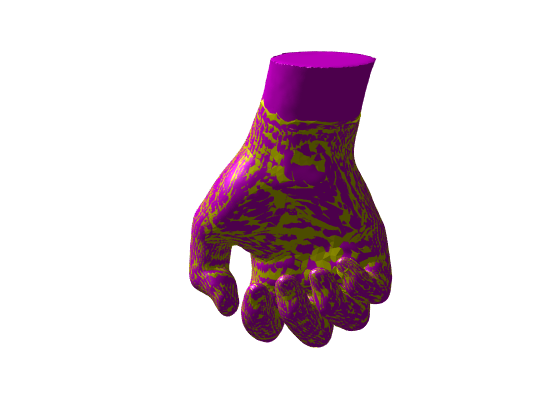

sourceV =   -76.3320   36.2372  119.9903
  -78.6323   35.1582  118.8979
  -73.4953   38.1865  121.0542
  -74.7488   36.5884  117.5564
  -77.1524   35.8451  116.8759
  -79.0495   35.2849  116.3668
  -76.0299   36.9834  122.9483
  -78.1113   35.4502  121.6130
  -74.1616   38.9201  124.7945
  -72.0868   37.5674  117.8993


targetV = points.vertices;
sourceV = mesh.vertices;
targetF = points.faces;
sourceF = mesh.faces;
iterations = 30;
flag_prealligndata = 1;
figureOn = 1;
rigidICP = 0;

[sourceV] = ICP_nonrigidICP(targetV, sourceV, targetF, sourceF, iterations, flag_prealligndata, figureOn, rigidICP)

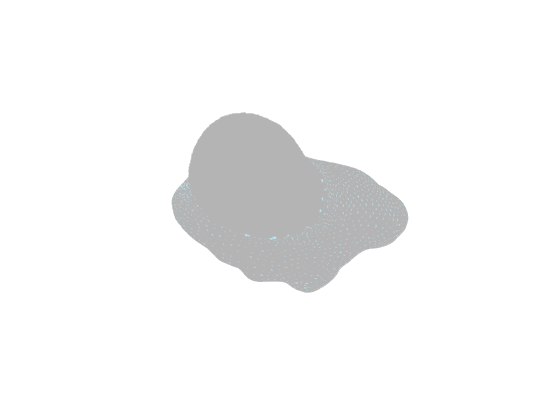


vertices_c = sourceV;
% clear targetV sourceV targetF sourceF 

figure()
axis equal
axis off
hold on
scatter3(points.vertices(:,1),points.vertices(:,2),points.vertices(:,3),'.', 'MarkerEdgeColor',[180/255, 180/255, 180/255]);
scatter3(sourceV(:,1),sourceV(:,2),sourceV(:,3),'.', 'MarkerEdgeColor',[190/255, 240/255, 251/255]);
%scatter3(centers_c(:,1),centers_c(:,2),centers_c(:,3),'o','MarkerEdgeColor',[255/255, 0/255, 0/255]);
hold off

## Save vertices

HY_pos7_vertices = sourceV; 
mesh.vertices = HY_pos7_vertices;
visualization
save HY_pos7_vertices.mat HY_pos7_vertices;

toc

